## Introduction

A testbed was developed to spectrally reproduce display stimuli for testing color calibration kits. The testbed, LightSim, consists of a tunable light source (TLS) for generating the target spectrum, an integrating sphere for diffusing the light for the color calibration sensor, computer hardware and software components for controlling the TLS, and a spectroradiometer for measuring the output spectrum. 

The testbed was treated as a 1-pixel, 1024-primary, 40,000-level display in contrast to the regular n-pixel, 3-primary, 256-level displays. The TLS used 1024 columns of a digital light processor (DLP) to selectively reflect the dispersed light coming from a xenon lamp after passing the grating. Each column was independently controlled by an integer value between 0 and 40,000 to form a bandpass filter with a bandwidth of 25 nm at a spectral resolution of 0.40 nm. The spectroradiometer measured the output spectrum between 380 nm and 780 nm at 1 nm resolution.

The final forward model accepts a vector of 1024 column values and predicts the output spectrum of 401 wavelengths.

To simulate the stimuli of a given display, the TLS model needed to be inversed by solving the 1024x401 matrix equation with the R General Purpose Optimization tool (optim L-BFGS-B). The inverse model accepts a target spectrum and then calculates the 1024 column values.

## Setup

Controlling OL490/HIMS1 and PR730 in WO62/3143


[ret hname] = system('hostname');
if isequal(hname(1:end-1),'wcc-FX')
    HIMS = 1;
else
    HIMS = 2;
end
HIMS

HIMS = 2


ol

ol =   OL490Class with properties:

                   m: [1×1 OL490_SDK_Dll.OL490SdkLibrary]
            asmCyUSB: []
        asmOLIPlugin: []
         asmOL490Lib: []
         asmOL490SDK: []
    max_column_value: 40000
           gamma_lut: [11×2 double]
           classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Class'
               vec_x: [1024×1 double]
               vec_y: [1024×1 double]
               vec_z: [1024×1 double]
                HIMS: 2


cs

cs =   cs2000Class with properties:

         ver: '6/28/2022'
     comPort: [1×1 rs232ClassCS2000]
    settings: 'CS2000'


ols = OL490Sim(HIMS)

ols =   OL490Sim with properties:

             col_spec: []
             HIMS_VER: 'HIMS2_07032022'
       spike_filename: 'spike_HIMS2_07032022.mat'
       gamma_filename: 'gamma_HIMS2_07032022.mat'
    col_spec_filename: 'col_spec_HIMS2_07032022.mat'
             speC_max: []
             speC_min: []
            reflC_min: []
            classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim'
        spikedatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/spike_HIMS2_07032022.mat'
     col_specdatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/col_spec_HIMS2_07032022.mat'
        gammadatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/gamma_HIMS2_07032022.mat'



CHARACTERIZING = 0

CHARACTERIZING = 0

ans = 'Set the light to green and show its spectrum'

Yxy =     4.5441    0.2893    0.6998


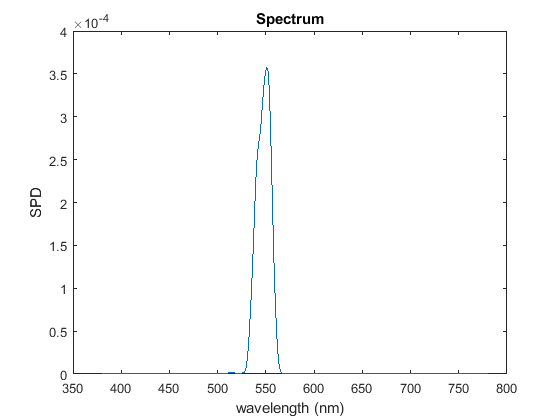


clf; ols.check_ol_cs(ol,cs)

## Collect gamma measurement data

Measure 0%, 10%,... 100% of the fully on output spectrum.

Use the area under the curve (i.e., total power, which should be proportional to luminance) to determine gamma.

In the characterization stage, 350 out of 1024 columns were measured to construct the look-up table of the spectral reflectance. To avoid the prolonged measurement time required by the spectroradiometer to collect a limited number of photons reflected by one column only, seven columns were activated simultaneously to generate eight spikes that were at least 50 nm apart without any cross-talking.

if CHARACTERIZING
    ols.FWD_stimulate_gamma (ol,cs)
end

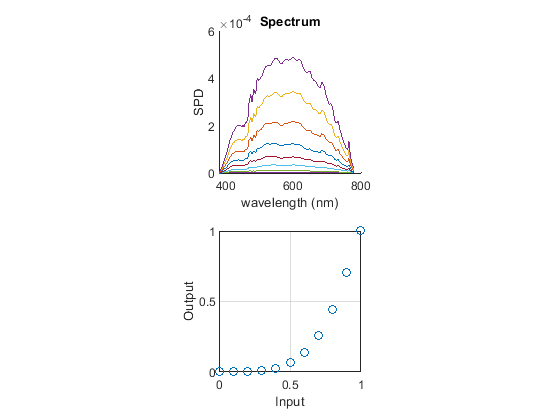

ols.FWD_stimulate_gamma_finding

## Collect spectral measurement data

if CHARACTERIZING
    ols.FWD_stimulate_spectrally (ol,cs)
end

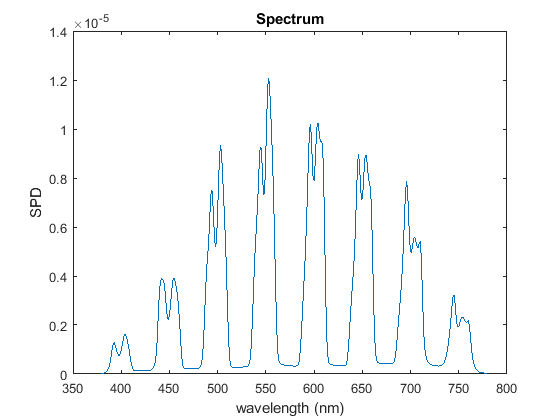

ols.FWD_stimulate_spectrally_finding

## Analyze spectral measurement data

ols.FWD_characterize_spectrally

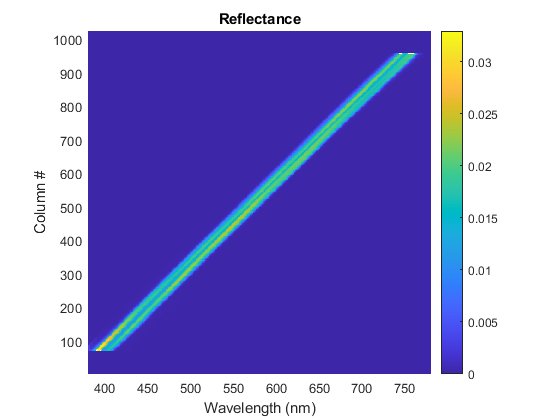

ols.FWD_characterize_spectrally_finding

## Check accuracy of the forward model

Column 1000 is not modeled because 780 nm is excluded in the combs.

col_range  = [100:100:1000];

vec = OL490Class.VEC_multiple_peaks(col_range);

refl = ols.FWD_vec2reflC(vec);
spec = ols.FWD_vec2spdC(vec);

clf
hold on
spec.plot

mea = ol.setColumn1024GammaandMeasure(vec,cs);

Yxy =     0.3477    0.3856    0.4142


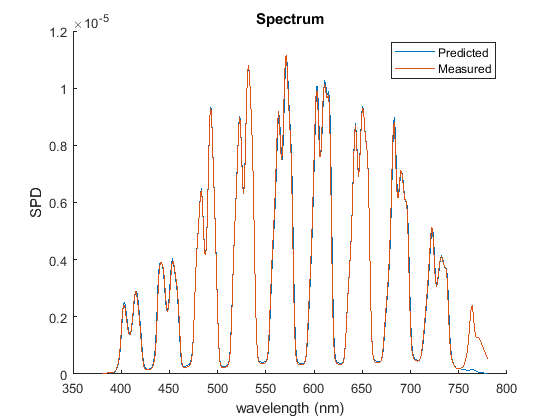

mea.plot

legend('Predicted','Measured')

## Check accuracy of the inverse model with 3 displays

Spectra of the red, green, and blue primaries of three displays were used to represent different color gamuts and lighting methods. A virtual reality device based on OLED (Oculus Rift), a professional-grade display based on CCFL-backlighting (NEC PA271), and a consumer-grade display based on LED-backlighting (HP Z24X) were measured to represent the DCI-P3, AdobeRGB, and sRGB color spaces. For each display, a model was created to accept the RGB input values and then predict the output spectrum.

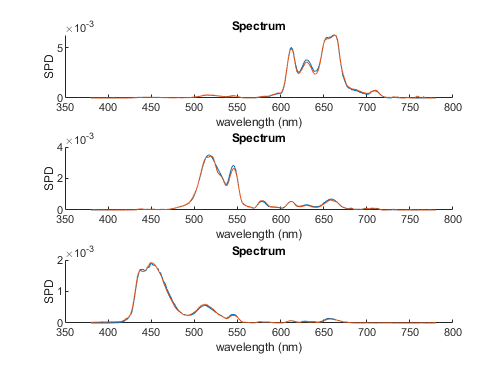

### NEC

disp_nec = NECPA271Sim(HIMS)

obj =   NECPA271Sim with properties:

            sc: 0.0400
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


disp_nec =   NECPA271Sim with properties:

            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


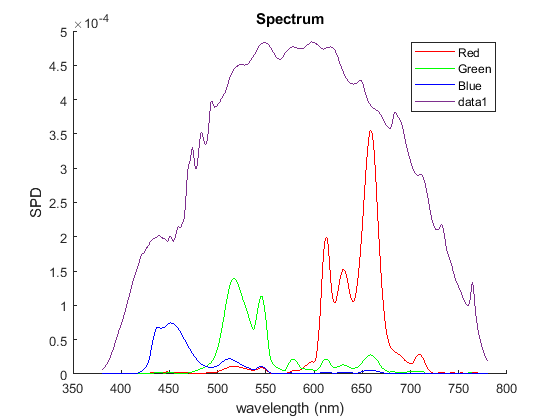

clf; check_RGB_primaries(ol,ols,cs,disp_nec)

Yxy =     2.0446    0.6489    0.3281


Yxy =     3.0590    0.2458    0.6550


Yxy =     0.4818    0.1587    0.1105


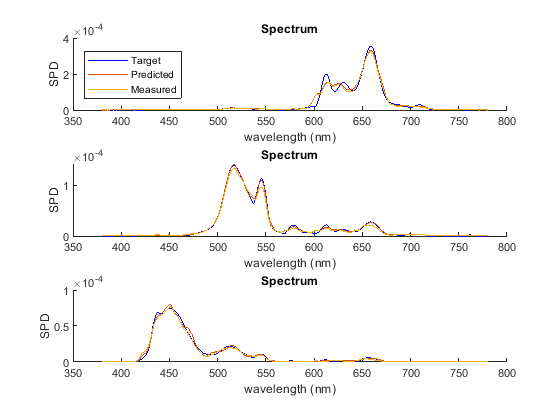

if CHARACTERIZING
    disp_nec.OL490_model(ols)
end
disp_nec.OL490_load_vec;

compare_RGB_primaries(ol,ols,cs,disp_nec)

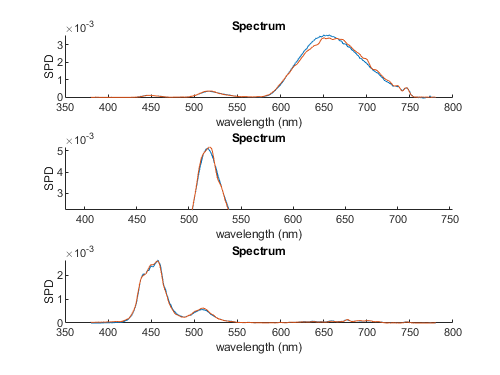

### HP

disp_hp = HPZ24xSim(HIMS)

obj =   HPZ24xSim with properties:

            sc: 0.0400
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


disp_hp =   HPZ24xSim with properties:

            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


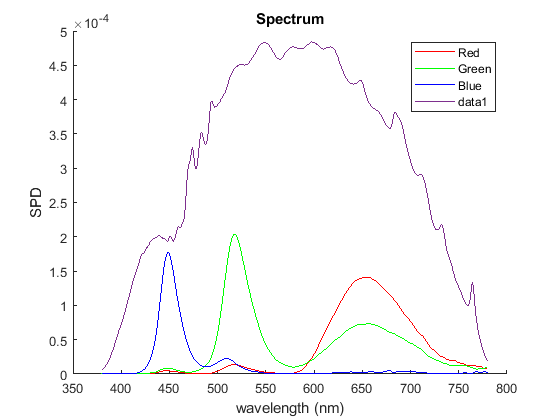

clf; check_RGB_primaries(ol,ols,cs,disp_hp)

Yxy =     1.3129    0.6281    0.3301


Yxy =     4.1050    0.3054    0.5817


Yxy =     0.4107    0.1539    0.0626


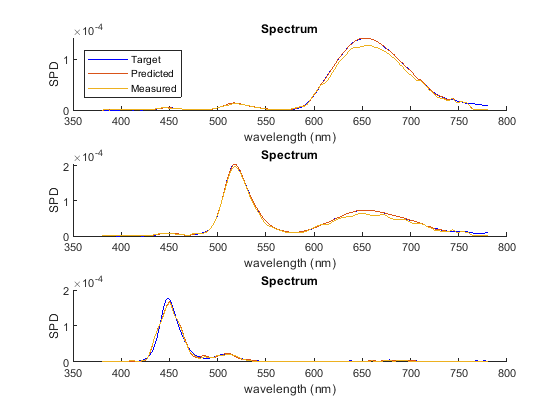

if CHARACTERIZING
    disp_hp.OL490_model(ols)
end
disp_hp.OL490_load_vec;

compare_RGB_primaries(ol,ols,cs,disp_hp)

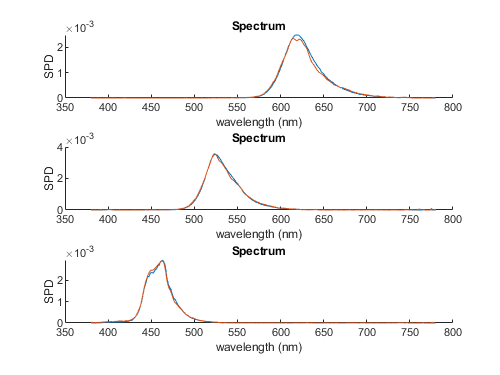

### Rift

disp_rift = RiftSim(HIMS)

obj =   RiftSim with properties:

      dataspec: []
        ramp_r: []
        ramp_g: []
        ramp_b: []
         lut_x: []
           lut: []
            sc: 0.0400
        spec_r: []
        spec_g: []
        spec_b: []
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@RiftSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


disp_rift =   RiftSim with properties:

      dataspec: [1024×401 double]
        ramp_r: [256×401 double]
        ramp_g: [256×401 double]
        ramp_b: [256×401 double]
         lut_x: [18×1 double]
           lut: [18×3 double]
            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@RiftSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


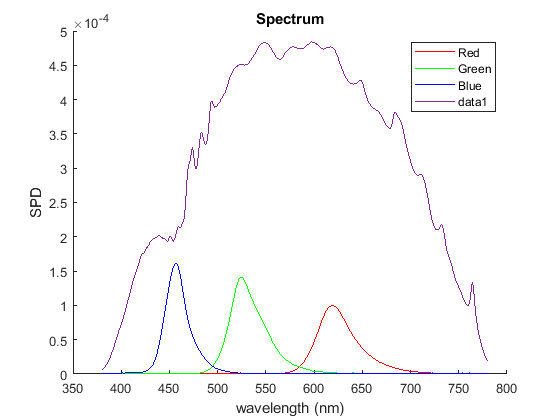

clf; check_RGB_primaries(ol,ols,cs,disp_rift)

Yxy =     1.0956    0.6616    0.3346


Yxy =     3.0659    0.2221    0.7120


Yxy =     0.2685    0.1462    0.0445


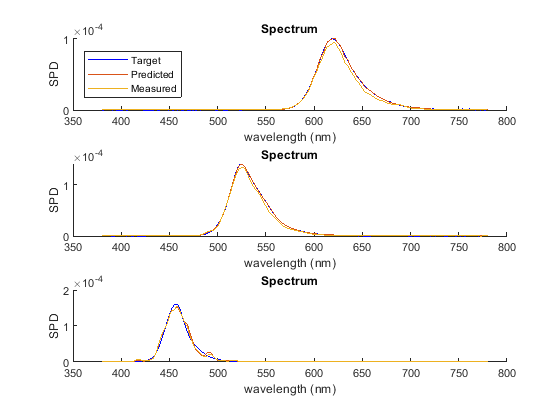


if CHARACTERIZING
    disp_rift.OL490_model(ols)
end
disp_rift.OL490_load_vec;
compare_RGB_primaries(ol,ols,cs,disp_rift)

## ColorChecker Experiments

In the experiment, a color calibration sensor (DataColor Spyder X Elite) was tested with the 24 patches following the ColorChecker design. Each spectrum was simultaneously measured by the spectroradiometer (Konica-Minolta CS2000a) as the ground truth. The subject sensor allowed the user to select one of four backlighting modes (“White LED”, “Standard LED”, “General”, and “GB LED”) for improving the estimation. The test results were evaluated using the CIEDE2000 color difference metric. The experiment results show adequate linearity of luminance responses in the mid-range. Most color differences were less than 2.5 ΔE00, except for the darkest patch #24, indicating the limited capability of measuring dark shades. None of the four backlighting modes outperformed the others, and two blue patches #8 and #13 generated the most diverse results. This exercise demonstrated the utility of the LightSim for emulating arbitrary spectra without employing actual displays based on different backlighting methods.

return

Try CIE D65

d65 = SpectrumClass.CIE_D(5000);
target_orig = d65.amplitude;

sc = 0.00002;
clf
hold on
ols.speC_max.plot
plot(380:780,target_orig*sc)

target = target_orig * sc;
vec = ols.INV_spd2vec(target);
vec_d50 = vec;

mea = ol.setColumn1024GammaandMeasure(vec,cs);
clf
hold on
plot(380:780,target)
mea.plot
mea.xyz

function check_RGB_primaries (ol,ols,cs,disp)
disp.show_spectra;
ols.speC_max.plot
end

function compare_RGB_primaries (ol,ols,cs,disp)

clf

subplot(3,1,1)
hold on
v = disp.vec_r;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_r,'b')
s_predicted.plot
mea.plot
legend('Target','Predicted','Measured')
legend('Location','west')

subplot(3,1,2)
hold on
v = disp.vec_g;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_g,'b')
s_predicted.plot
mea.plot

subplot(3,1,3)
hold on
v = disp.vec_b;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_b,'b')
s_predicted.plot
mea.plot

end